# Plot

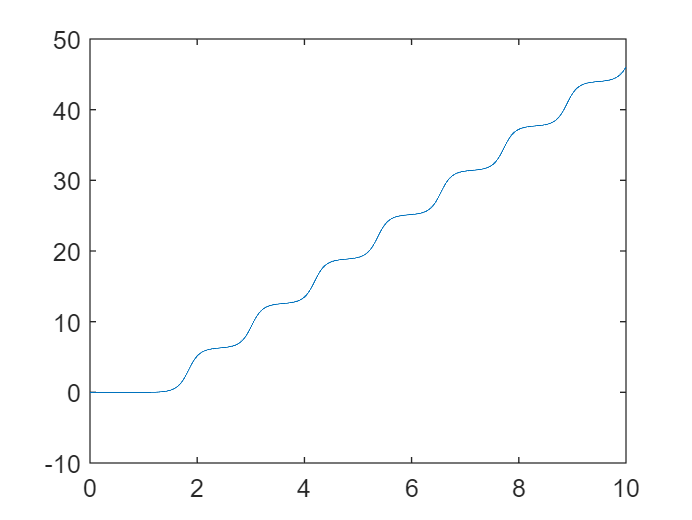


% plot time-position graphs 


% motion without PID control unit
Regler.P = 0;
Regler.I = 0;
Regler.D = 0;


sim('Viereck_Regler',Simulation_Time); %run simulation
x1 = out.pos.Time;
y1 = out.pos.Data;
figure(1);
plot(x1,y1);


% motion with PID control unit
%optimzed PID values determined through the Simulink PID Tune function
Regler.P = 153.209699315125;
Regler.I = 0.902695743521356;
Regler.D = 3062.83481362525;

sim('Viereck_Regler',Simulation_Time); %run simulation

figure(2);
x2 = out.pos.Time;
y2 = out.pos.Data;
plot(x2,y2);



